# McColl_2023_modelExecution 

clear, clc, close all

% update file name to the location folder is locally saved
FolderPath = fileparts('/Users/taylormccoll/Documents/SFU/1. Ph.D./1. Research Projects/1. Network Feedback/6. Manuscript/Manuscript Versions/230912_revision/Manuscript/MuscleProteinSynthesisKineticModel/GitHub/McColl_2023_Muscle Protein Synthesis Kinetic Model_231024/');
addpath(genpath(FolderPath)) % add all subfolders within 'FolderPath'

## File Output

Creates an 'Output Plots' folder with a subplot of the current date and time.

FilePath = fullfile(FolderPath, 'Output Plots/');
NewFolder = datestr(now, 'yy-mm-dd HH-MM-SS');
    CumulativeOutput = mkdir(FilePath, NewFolder);
FilePathCumulative = fullfile(FilePath, NewFolder);

## Model Inputs

GlucoseInfRate = 75e-3 *(1/180.16); % 75 mg/min glucose infusion; converted to units of moles/min
LeucineInfRate = 2.5e-3*(1/131.17); % 25 mg/min leucine infusion; converted to units of moles/min

% Subject specific data (used to calculate compartment volumes)
gender = 1; % 1=male, 0=female
height = 173; % cm
mass = 72.1; % kg
age = 41.9; % years
bia = 517; % Bioelectical Impedance (Ohms)
subjectData = [gender, height, mass, age, bia];

% Initial Conditions
x0 = xlsread('231023_Initial Values, IOM', '3. Oscillatory insulin'); % reduced phospho-proteins

% K-Values
KValueVector_given = xlsread('230922_K-values, IOM', '230930');

%Experimental Data
ExpData = '230221_experimental data.xlsx';

## Figure 2a: Model calibration

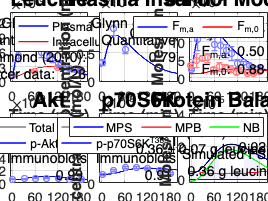

Cost_Indiv =     3.0000    0.7865
    4.0000    0.3834
    6.0000    1.2307
   21.0000    0.9855
   28.0000    0.9143
   41.0000    0.5042
   42.0000    0.8840
   46.0000    0.0184


Cost_Total = 5.7070

FSR_integral = 0.3587

% Simulated Protocol
Protocol = "Calibration, young adults";

EquilibriumDuration = 300;
RunDuration = 600;

% Model Simulation
[t, x, x_conc, expData_conc, expData_mass, CostParameters, interventionDuration, plasmaVolume, skelMusVolume] = ...
    runModel_OIM_230922(Protocol, ExpData, subjectData, x0, KValueVector_given, EquilibriumDuration, ...
    RunDuration, GlucoseInfRate, LeucineInfRate);

% 3-Pool Model - parameter comparison
ThreePoolModel_expData = xlsread('200831_Biolo, 3-pool parameters'); %nmol/min
[Title, Parameters, ThreePool_baseline] = ThreePoolParameters_baseline(x, t, KValueVector_given(:,2), ...
    EquilibriumDuration, ThreePoolModel_expData);

clf

% Figure 2a: Model calibration
figNum = 1;
FileName = sprintf('Figure 2a_model calibration - %s', datestr(now, 'yy-mm-dd HH-MM-SS'));
FilePath = FilePathCumulative;

[Cost_Indiv, Cost_Total, FSR_integral] = plot_Figure_2a_230925(figNum, t, x_conc, x, expData_conc, CostParameters, ...
    RunDuration, EquilibriumDuration, FilePath, FileName, KValueVector_given(:,2), interventionDuration)

## Figure 2b,c: model validation

ValidationProtocols = ["Valid., Mitchell (2015) bolus", "Valid., Mitchell (2015) pulse"];

for n = 1:length(ValidationProtocols)
    
    modelProtocol = ValidationProtocols(n);
    
    [t, x, x_conc, expData_conc, expData_mass, CostParameters, interventionDuration, plasmaVolume, skelMusVolume] = ...
        runModel_OIM_230922(modelProtocol, ExpData, subjectData, x0, KValueVector_given, EquilibriumDuration, ...
        RunDuration, GlucoseInfRate, LeucineInfRate);
       
    clf
    figNum = 1+n;   
    validationSimulation = ["Mitchell et al., bolus", "Mitchell et al., pulsatile"];
    validationPlot_letter = ["b", "c"];
    FileName = sprintf('Figure 2%s_model validation - %s - %s.eps', validationPlot_letter(n), validationSimulation(n), ...
        datestr(now, 'yy-mm-dd HH-MM-SS'));
    FilePath = FilePathCumulative;

    % Figure 2b,c: Main text validation plot (4 subplots)
    plot_Figure_2bc_230925(figNum, t, x_conc, x, expData_conc, CostParameters, RunDuration, EquilibriumDuration, ...
        FilePath, FileName, KValueVector_given(:,2), interventionDuration);
end

## Figure S1: comprehensive model validation

modelProtocol = "Valid., Glynn (2010) 1.85g"

modelProtocol = "Valid., Mitchell (2015) bolus"

modelProtocol = "Valid., Mitchell (2015) pulse"

modelProtocol = "Valid., Wilkinson (2013)"

modelProtocol = "Valid., Drummond (2010)"

modelProtocol = "Valid., Dickinson (2011) cntl"

ValidationProtocols = ["Valid., Glynn (2010) 1.85g", ...
    "Valid., Mitchell (2015) bolus", "Valid., Mitchell (2015) pulse", ...
    "Valid., Wilkinson (2013)", ...
    "Valid., Drummond (2010)", ...
    "Valid., Dickinson (2011) cntl"];

for n = 1:length(ValidationProtocols)
    
    modelProtocol = ValidationProtocols(n)
    
    [t, x, x_conc, expData_conc, expData_mass, CostParameters, interventionDuration, plasmaVolume, skelMusVolume] = ...
        runModel_OIM_230922(modelProtocol, ExpData, subjectData, x0, KValueVector_given, EquilibriumDuration, ...
        RunDuration, GlucoseInfRate, LeucineInfRate);
    
    clf, close all 
    figNum = 3+n;
    S2_letter = 'a':'f';
    FileName = sprintf('Figure S1%s_%s - %s.eps', S2_letter(n), modelProtocol, datestr(now, 'yy-mm-dd HH-MM-SS'));
    FilePath = FilePathCumulative;
    
    % Figure S2: Comprehensive validation plot (6 subplots per study)
    [Cost_Indiv, Cost_Total, FSR_integral] = plot_Figure_S1_230926(figNum, t, x_conc, x, expData_conc, CostParameters, ...
        RunDuration, EquilibriumDuration, FilePath, FileName, modelProtocol, KValueVector_given(:,2), interventionDuration);  
end

## Figure S2: discrepant plasma leucine measurements

LeucineMethodProtocols = ["Calibration, young adults", "Valid., Glynn (2010) 1.85g", "Valid., Drummond (2010)", ...
    "Valid., Dickinson (2011) cntl", "Valid., Mitchell (2015) bolus", "Valid., Wilkinson (2013)", ...
    "Atherton (2010) - bolus", "Moore (2009)", "Mazzulla (2017)"];

clf, close all

for i = 1:length(LeucineMethodProtocols)
    
    LeucineSimProtocol = LeucineMethodProtocols(i);
    
    LeucineSimProtocol_title = ["Glynn (2010)", "Glynn (2010)", "Drummond (2010)", "Dickinson (2011)", ...
        "Mitchell (2015)", "Wilkinson (2013)", ...
        "Atherton (2010)", "Moore (2009)", "Mazzulla (2017)"];    

    [t, x, x_conc, expData_conc, expData_mass, CostParameters, interventionDuration, plasmaVolume, skelMusVolume] = ...
        runModel_OIM_230922(LeucineSimProtocol, ExpData, subjectData, x0, KValueVector_given, EquilibriumDuration, ...
        RunDuration, GlucoseInfRate, LeucineInfRate);
    
    figNum = 10;
    FileName_leuMethod = sprintf('Figure S2_discrepant leucine measurements - %s', datestr(now, 'yy-mm-dd HH-MM-SS'));
    FilePath = FilePathCumulative;
    
    LeucineDose = [3.5, 1.85, 3.5, 1.8, 3.59, 3.42, 4.1, 2.1, 1.64]; % corroborates with protocol order
    
    [Cost_Indiv, Cost_Total] = plot_Figure_S2_230418(figNum(1), t, x_conc, x, expData_conc, CostParameters, ...
        RunDuration, EquilibriumDuration, LeucineSimProtocol_title(i), ...
        KValueVector_given(:,2), interventionDuration, LeucineDose(i), i);
end

prompt = 'Save figure? Y/N: ';  
SaveFile = input(prompt,'s');
if SaveFile == 'Y'
    figure1 = figure(figNum(1));
    figfile1 = fullfile(FilePath, FileName_leuMethod);
    saveas(figure1, figfile1, 'epsc' );
end

## Figure S3: Simulation of all unmeasured species from the model calibration

CostParameters =      3     4     6    21    28    41    42    46     5


% Simulated Protocol
Protocol = "Calibration, young adults";

% Model Simulation
[t, x, x_conc, expData_conc, expData_mass, CostParameters, interventionDuration, plasmaVolume, skelMusVolume] = ...
    runModel_OIM_230922(Protocol, ExpData, subjectData, x0, KValueVector_given, EquilibriumDuration, ...
    RunDuration, GlucoseInfRate, LeucineInfRate);

figNum=11;
FileName = sprintf('Figure S3_calibration, simulation of all unmeasured species - %s', Protocol, ...
    datestr(now, 'yy-mm-dd HH-MM-SS'));

plot_Figure_S3_230923(figNum, t, x_conc, x, expData_conc, CostParameters, ...
    RunDuration, EquilibriumDuration, FilePath, FileName, KValueVector_given(:,2), interventionDuration);

## Glucose and insulin dynamic

Simulation of the glucose and insulin time-courses. Data not presented in the manuscript.

clf
figure(12);
xTicksSeq = 0:60:RunDuration;
xTicks = EquilibriumDuration+xTicksSeq;

% Plasma insulin
subplot(1,2,1)
    plot(t, x_conc(:,3))
    grid on
    xlim([300 600])
        xticks(xTicks)
        xticklabels(xTicksSeq)
    ylim([0 10e-11])
    title('Plasma Insulin')
    ylabel('Concentration (mol/L)')
    xlabel('Time (min)')
% Plasma glucose
subplot(1,2,2)
    plot(t, x_conc(:,36))
    grid on
    xlim([300 600])
        xticks(xTicks)
        xticklabels(xTicksSeq)
    ylim([0 5e-3])
    title('Plasma Glucose')
    ylabel('Concentration (mol/L)')
    xlabel('Time (min)')

## Figure 3 & 6: Knockdown of leucine and insulin signaling, respectively

Moderated knockdown of leucine signaling (via r39: leucine mediate mTORC1 activity) or insulin signaling (via r16: insulin mediated IR_b phosphorylation)

Protocol = "Signaling knockdown";

Kd_Rxns = [39, 16]; % Kd leucine signalling or insulin signaling
Kd_Variations = [0, 25, 50, 75, 90]; % percent knockdown for each rxn
Kd_Variations_legend = {'1x', '0.75x', '0.50x', '0.25x', '0.10x'}; % fold change for each reaction

close all
clf

% Simulation for each of the knockdown reactions
for k = 1:length(Kd_Rxns)
      
    %selecting the specific rxn to knockdown
    Kd_Rxns_for = Kd_Rxns(k);

    %creating file names for each plot
    figNumber_manuscript = ["3", "6"];
    kd_stimuli = ["leucine", "insulin"];
    FileName_signalling = sprintf('Figure %s_knockdown of %s signaling - %s', figNumber_manuscript(k), kd_stimuli(k), ...
        datestr(now, 'yy-mm-dd HH:MM:SS'));
    figNum=[12+k];
    
    %For loop to run through the knockdown variations
    for i = 1:length(Kd_Variations);
        
        %creating array with given k-values
        Kd_Kvalue = KValueVector_given(:,1:2);
        
        %scaling the k-value of the selected rxn to variation(i)
        Kd_Kvalue(Kd_Rxns_for,2) = ((100 - Kd_Variations(i))/100) * Kd_Kvalue(Kd_Rxns_for,2);
        
        %run simulation
        [t, x, x_conc, expData_conc, expData_mass, CostParameters, interventionDuration, plasmaVolume, skelMusVolume] = ...
            runModel_OIM_230922(Protocol, ExpData, subjectData, x0, KValueVector_given, EquilibriumDuration, RunDuration, ...
            GlucoseInfRate, LeucineInfRate, Kd_Kvalue);
        
        % Plotting Fig 3 or 6    
        %line/color varations for the plot (needs to have same length as number of Kd_variations
        style_variation = {'-', '--', ':', '-.','--'};
        color_variation = 1-(0 : (1-0.25)/4 : .75); % 0.25 to 0.75; equally spaced
        
        % change the FSR values being written in the MPS subplot
        plot_Figure_3_6_230926(figNum, t, x_conc, x, RunDuration, EquilibriumDuration, KValueVector_given(:,2), ...
            interventionDuration, style_variation{i}, color_variation(i), Kd_Variations_legend{i}, Kd_Rxns_for)
    end
    
    prompt = 'Save figure? Y/N: ';  
    SaveFile = input(prompt,'s');
    
    if SaveFile == 'Y'
        figure1 = figure(figNum(1));
        figfile1 = fullfile(FilePath, FileName_signalling);
        saveas(figure1, figfile1, 'epsc' );
    else
    end
    
end

mps_integal = 0.3587

nb_integral = 0.2700

mps_integal = 0.3224

nb_integral = 0.2322

mps_integal = 0.2750

nb_integral = 0.1816

mps_integal = 0.2051

nb_integral = 0.1029

mps_integal = 0.1340

nb_integral = 0.0108

## Figure S4: simulation of orally ingested rapamycin

Rapamycin is a potent, mTORC1 specific inhibitor.

Protocol = "Valid., Dickinson (2011) rap";

Kd_Rxn = 39; % mTORC1 activation
Kd_Variations = 95; % percent knockdown of kd_rxn

%scaling the k-value of the selected rxn to variation(i)
kValue_kd = KValueVector_given(:,1:2);
kValue_kd(Kd_Rxn,2) = ((100 - Kd_Variations)/100) * kValue_kd(Kd_Rxn,2);

%run simulation
[t, x, x_conc, expData_conc, expData_mass, CostParameters, interventionDuration, plasmaVolume, skelMusVolume] = ...
    runModel_OIM_230922(Protocol, ExpData, subjectData, x0, kValue_kd, EquilibriumDuration, RunDuration, ...
    GlucoseInfRate, LeucineInfRate, []);

figNum=15;
FileName = sprintf('Figure S4_rapamycin ingestion, %s - %s.eps', Protocol, datestr(now, 'yy-mm-dd HH-MM-SS'));
FilePath = FilePathCumulative;

% Plot Figure S4
[Cost_Indiv, Cost_Total, FSR_integral] = plot_Figure_S4_230926(figNum, t, x_conc, x, expData_conc, ...
    CostParameters, RunDuration, EquilibriumDuration, FilePath, FileName, KValueVector_given(:,2), ...
    interventionDuration);

## Figure 4: Basal p70S6K levels influence MPS

Protocol = "Basal p70S6K Analysis";

IV_change = 27; % Increasing  p70S6K levels
IV_variation = [1, 2, 4]; % factor to increase both IV's
IV_variation_legend = {'1x', '2x', '4x'};

%creating file names for  plot
FileName_signalling = sprintf('Figure 4_%s - %s', Protocol,  datestr(now, 'yy-mm-dd HH:MM:SS'));
figNum=16;    

close all
clf
%for loop to plot each change in IV
for k = 1:length(IV_variation)

    %adjusting the IV data set
    basalAnalysisIV = x0;
    basalAnalysisIV(IV_change,1) = basalAnalysisIV(IV_change,1).*IV_variation(k);

    %run simulation
    [t, x, x_conc, expData_conc, expData_mass, CostParameters, interventionDuration, plasmaVolume, skelMusVolume] = ...
        runModel_OIM_230922(Protocol, ExpData, subjectData, basalAnalysisIV, KValueVector_given, EquilibriumDuration, RunDuration, ...
        GlucoseInfRate, LeucineInfRate, []);

        %line/color varations for the plot (needs to have same length as
        %Kd_variations
        style_variation = {'-', '--', ':', '-.','--'};
        color_variation = 1-(0 : (1-0.25)/4 : .75); % 0.25 to 0.75; equally spaced

    [MPS_integral, p_p70S6K_integral] = plot_Figure_4_230926(figNum, t, x_conc, x, RunDuration, EquilibriumDuration, ...
        KValueVector_given(:,2), interventionDuration, style_variation{k}, color_variation(k), IV_variation_legend{k})

ratio = x_conc(3001,28)/x_conc(3001,27)
end

MPS_integral = 0.3587

p_p70S6K_integral = 3.1478e-07

ratio = 0.1530

MPS_integral = 0.4985

p_p70S6K_integral = 4.6305e-07

ratio = 0.1065

MPS_integral = 0.6651

p_p70S6K_integral = 6.6475e-07

ratio = 0.0737


prompt = 'Save figure? Y/N: ';
SaveFile = input(prompt,'s');

if SaveFile == 'Y'
    figure1 = figure(figNum(1));
    figfile1 = fullfile(FilePath, FileName_signalling);
    saveas(figure1, figfile1, 'epsc' );    
else
end

## Figure S5: p-p70S6K signaling is required for maximal MPS

p70S6K maintained at basal levels (mTORC1 mediated signalling removed)

Cost_Indiv =     3.0000    0.7865
    4.0000    0.3834
    6.0000    1.2307
   21.0000    0.9855
   28.0000    0.9143
   41.0000    0.5042
   42.0000    0.8840
   46.0000    0.0184


Cost_Total = 5.7070

FSR_integral = 0.3587

% Figure S5(A)
% p70S6K signaling sensitive (calibration simulation)
Protocol = "Calibration, young adults";

% Model Simulation
[t, x, x_conc, expData_conc, expData_mass, CostParameters, interventionDuration, plasmaVolume, skelMusVolume] = ...
    runModel_OIM_230922(Protocol, ExpData, subjectData, x0, KValueVector_given, EquilibriumDuration, ...
    RunDuration, GlucoseInfRate, LeucineInfRate);

% Plot
clf
figNum=17;
FileName = sprintf('Figure S5A_p-p70S6K signaling and MPS, p-p70S6K sensitive  - %s', ...
    datestr(now, 'yy-mm-dd HH-MM-SS'));
FilePath = FilePathCumulative;

[Cost_Indiv, Cost_Total, FSR_integral] = plot_Figure_S5a_230926(figNum, t, x_conc, x, expData_conc, ...
    CostParameters, RunDuration, EquilibriumDuration, FilePath, FileName, KValueVector_given(:,2), ...
    interventionDuration)


% % Reference line for Figure S5B
% [Cost_Indiv, Cost_Total, FSR_integral] = plot_Figure_S5a_230926_ref(figNum, t, x_conc, x, expData_conc, ...
%     CostParameters, RunDuration, EquilibriumDuration, FilePath, FileName, KValueVector_given(:,2), ...
%     interventionDuration);

Cost_Indiv =     3.0000    0.7866
    4.0000    0.3792
    5.0000    0.6598
   21.0000    0.9932
   28.0000    1.7352
   41.0000    0.5086
   42.0000    0.9066
    6.0000    1.2728
   46.0000    1.6360


Cost_Total = 8.8779

FSR_integral = 0.2406

% Figure S5(B)
% p-p70S6K maintained at basal levels (i.e., no stimululation following
% leucine ingestion)
Protocol = "Calibration, young adults";

% Model Simulation
[t, x, x_conc, expData_conc, expData_mass, CostParameters, interventionDuration, plasmaVolume, skelMusVolume] = ...
    runModel_OIM_230926_signallingPermissive(Protocol, ExpData, subjectData, x0, KValueVector_given, EquilibriumDuration, ...
    RunDuration, GlucoseInfRate, LeucineInfRate);

% Plot
close all
figNum=18;
FileName = sprintf('Figure S5B_p-p70S6K signaling and MPS, p70S6K turned off  - %s', datestr(now, 'yy-mm-dd HH-MM-SS'));
FilePath = FilePathCumulative;

[Cost_Indiv, Cost_Total, FSR_integral] = plot_Figure_S5b_230926(figNum, t, x_conc, x, expData_conc, CostParameters, ...
    RunDuration, EquilibriumDuration, FilePath, FileName, KValueVector_given(:,2), interventionDuration)

## Figure 5: enhanced mTORC1 activity can compensate for loss of p70S6K levels

Moderated reduction in p70S6K levels with moderated increases in mTORC1 kinase activity

MPS_integral = 0.3587

p_p70S6K_integral = 3.1490e-06

MPS_integral = 0.4640

p_p70S6K_integral = 4.2641e-06

MPS_integral = 0.5802

p_p70S6K_integral = 5.6229e-06

MPS_integral = 0.2454

p_p70S6K_integral = 2.0665e-06

MPS_integral = 0.3208

p_p70S6K_integral = 2.7898e-06

MPS_integral = 0.4026

p_p70S6K_integral = 3.6330e-06

MPS_integral = 0.1591

p_p70S6K_integral = 1.3035e-06

MPS_integral = 0.2086

p_p70S6K_integral = 1.7460e-06

MPS_integral = 0.2600

p_p70S6K_integral = 2.2299e-06

MPS_integral = 0.3776

p_p70S6K_integral = 3.4694e-06

MPS_integral = 0.0976

p_p70S6K_integral = 7.8674e-07

MPS_integral = 0.1274

p_p70S6K_integral = 1.0413e-06

MPS_integral = 0.1563

p_p70S6K_integral = 1.2985e-06

MPS_integral = 0.2193

p_p70S6K_integral = 1.9121e-06

Protocol = "p70S6K reduced, mTORC1 kinase increased";

IV_change = [27,28]; % 27+28: p70S6K + p-p70S6K
IV_variation = [1, .5, .25, 0.125]; % factor to increase levels of p70S6K and p-p70S6K
IV_variation_legend = {'1x', '0.5x', '0.25x', '0.125x'};

kValue_change = [40]; % k40 -> modulating mTORC1 mediated p70S6K phosphorylation acivity
% mtorc1Kinase_increase = [1;1;1;1];
mtorc1Kinase_increase = [1, 2, 4, nan; ...
    1,2,4,nan; ...
    1,2,4,32; ...
    1,2,4,64];
mtorc1Kinase_increase_legend = {'1x', '2x', '4x', nan; ...
    '1x', '2x', '4x', nan;
    '1x', '2x', '4x', '32x';
    '1x', '2x', '4x', '64x'};

close all
clf

for i = 1:length(IV_variation)

    %p70S6K IV
    p70S6K_IV = x0;
    p70S6K_IV(IV_change,1) = p70S6K_IV(IV_change,1).*IV_variation(i);

    % creating file names for  plot
    Fig5_letter = ['a','b','c','d'];
    FileName_signalling = sprintf('Figure 5%s_p70S6K level at %s, mTORC1 kinase increased - %s.eps', ...
        Fig5_letter(i), IV_variation_legend{i}, datestr(now, 'yy-mm-dd HH:MM:SS'));
    figNum=18+i;  
    
        %for loop to plot each change in mTORC1 kinase activity
        mtorc1Kinase_increase_iteration = mtorc1Kinase_increase(i,:);

        for k = 1:length(mtorc1Kinase_increase_iteration(~isnan(mtorc1Kinase_increase_iteration)))
        
            %adjusting the mTORC1 kinase k-value
            mtorc1Kinase_kv = KValueVector_given;
            mtorc1Kinase_kv(kValue_change,2) = mtorc1Kinase_kv(kValue_change,2).*mtorc1Kinase_increase_iteration(k);
        
            %run simulation
            [t, x, x_conc, expData_conc, expData_mass, CostParameters, interventionDuration, plasmaVolume, ...
                skelMusVolume] = runModel_OIM_230922(Protocol, ExpData, subjectData, p70S6K_IV, mtorc1Kinase_kv, ...
                EquilibriumDuration, RunDuration, GlucoseInfRate, LeucineInfRate, []);
        
                %line/color varations for the plot (needs to have same length as mtorc1Kinase_variations
                style_variation = {'-', '--', ':', '-.','-'};
                color_variation = 1-(0 : (1-0.25)/4 : .75); % 0.25 to 1; equally spaced
                lineThickness_variation = [2.5, 1.5, 1.5, nan; 1.5, 1.5, 1.5, nan; 1.5, 1.5, 1.5, 1.5; ...
                    1.5, 1.5, 1.5, 1.5]; % increased thickness for reference MPS curve (1x p70S6K, 1x mTORC1 kinase)
        
            [MPS_integral, p_p70S6K_integral] = plot_Figure_5_230926(figNum, t, x_conc, x, RunDuration, ...
                EquilibriumDuration, KValueVector_given(:,2), interventionDuration, style_variation{k}, ...
                color_variation(k), mtorc1Kinase_increase_legend{i,k}, IV_variation_legend{i}, lineThickness_variation(i,k))     
        end
        
        prompt = 'Save figure? Y/N: ';  %add code to save both figures
        SaveFile = input(prompt,'s');
        
        if SaveFile == 'Y'
            figure1 = figure(figNum);
            figfile1 = fullfile(FilePath, FileName_signalling);
            saveas(figure1, figfile1, 'epsc' );    
        else
        end
end

## Figure 7: p70S6K negative feedback pathway analysis

Analyzing the influence of the IRS1 and mTORC1 feedback pathways on p70S6K signalling and MPS

MPS_integral = 0.3573

p_p70S6K_integral = 3.1454e-07

MPS_integral = 0.3578

p_p70S6K_integral = 3.1462e-07

MPS_integral = 0.3587

p_p70S6K_integral = 3.1478e-07

MPS_integral = 0.3605

p_p70S6K_integral = 3.1517e-07

MPS_integral = 0.3667

p_p70S6K_integral = 3.1677e-07

MPS_integral = 0.5380

p_p70S6K_integral = 5.1984e-07

MPS_integral = 0.4373

p_p70S6K_integral = 3.9940e-07

MPS_integral = 0.3587

p_p70S6K_integral = 3.1478e-07

MPS_integral = 0.2856

p_p70S6K_integral = 2.4193e-07

MPS_integral = 0.2046

p_p70S6K_integral = 1.6637e-07

Protocol = "Calibration, young adults";
testParameters = [21, 43]; % the two parameters that incorporate negative feedback

% Sensitivity Analysis - inputs
SA_variations = [.2, .5, 1, 2, 5];
SA_variations_legend = {'0.2x', '0.5x', '1x', '2x', '5x'};

close all
% Sensitivity analysis for each negative feedback parameter
for k = 1:length(testParameters)
    
    %creating file names for  plot
    figure7_letter = ['a','b'];
    figure7_reaction = {'IRS1 feedback', 'mTORC1 feedback'};
    FileName_p70S6K_SA = sprintf('Figure 7%s_p70S6K negative feedback sensitivity analysis, %s - %s', ...
        figure7_letter(k), figure7_reaction{k},  datestr(now, 'yy-mm-dd HH:MM:SS'));
    figNum=21+k;

    % Sensitivity Analysis - loop (3 runs per tested parameter)
    for i = 1:length(SA_variations)
    
        SA_kValues = KValueVector_given;
        SA_kValues(testParameters(k), 2) = KValueVector_given(testParameters(k),2)*SA_variations(i);
    
        [t, x, x_conc, expData_conc, expData_mass, CostParameters, interventionDuration, plasmaVolume, skelMusVolume] = ...
            runModel_OIM_230922(Protocol, ExpData, subjectData, x0, SA_kValues, EquilibriumDuration, ...
            RunDuration, GlucoseInfRate, LeucineInfRate);
    
        % line/color varations for the plot (needs to have same length as mtorc1Kinase_variations
        style_variation = {':', '-.', '-', '-.', ':'};
        color_variation = 1-(0 : (1-0.25)/5 : .75); % 0.25 to 1; equally spaced
    
        if isequal(testParameters(k), 21)
            [MPS_integral, p_p70S6K_integral] = plot_Figure_7a_230926(figNum, t, x_conc, x, RunDuration, ...
                EquilibriumDuration, KValueVector_given(:,2), interventionDuration, style_variation{i}, ...
                color_variation(i), SA_variations_legend{i})  

        elseif isequal(testParameters(k), 43)
            [MPS_integral, p_p70S6K_integral] = plot_Figure_7b_230926(figNum, t, x_conc, x, RunDuration, ...
                EquilibriumDuration, KValueVector_given(:,2), interventionDuration, style_variation{i}, ...
                color_variation(i), SA_variations_legend{i})       
        end
    end
    
    prompt = 'Save figure? Y/N: ';
    SaveFile = input(prompt,'s');
    
    if SaveFile == 'Y'
        figure1 = figure(figNum);
        figfile1 = fullfile(FilePath, FileName_p70S6K_SA);
        saveas(figure1, figfile1, 'epsc' );    
    else
    end
end